## CHANNEL EQUALIZATION

#### 1- Signal Model 


N = 500; % Number of symbols in s
P = 4;
sigma = 0.5;

s = (sign(randn(N,1))/sqrt(2)) + 1i*(sign(randn(N,1))/sqrt(2));
%idx = randi([1, 4], 1, N);
%s = sy(idx);

x = gendata_conv(s, P, N, sigma);

#### 2- P = 4 

X = zeros(2*P, N-1);
for i = 1:N-1
    X(:, i) = x((i-1)*P+1:(i+1)*P);
end

rank_X = rank(X);
fprintf('The rank of X is %d.\n',rank_X);

The rank of X is 8.


#### 3- Douple P $\to$P = 8

% Double P
x_2P = gendata_conv(s, 2*P, N, sigma);
X_2P = zeros(2*2*P, N-1);
for i = 1:N-1
    X_2P(:, i) = x_2P((i-1)*2*P+1:(i+1)*2*P);
end

rank_X_2P = rank(X_2P);
fprintf('The rank of X is %d.\n',rank_X_2P);

The rank of X is 16.


#### Zero-forcing and Wiener Equalizer

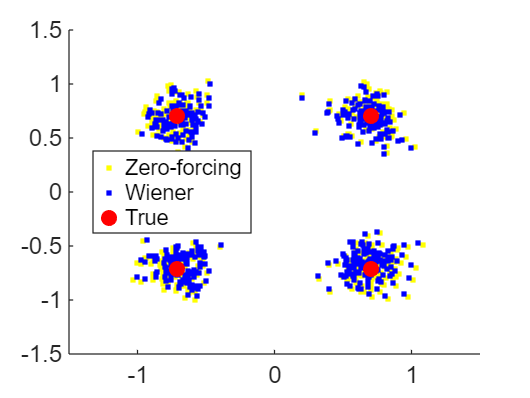

N = 500; % Number of symbols in s
P = 4;
sigma = 0.5;

[S_zf, S_wn, H] = ZF_Wn_reciever(s, P,N,sigma);

Real_zf = real(S_zf);
Imag_zf = imag(S_zf);

Real_wn = real(S_wn);
Imag_wn = imag(S_wn);

real_s = real(s);
imag_s = imag(s);

scatter(Real_zf(1, :), Imag_zf(1, :), 'green', '.');

hold on
scatter(Real_wn(1, :), Imag_wn(1, :), 'blue', '.');

scatter(real_s, imag_s, 'red', 'filled');

hold off
legend({'Zero-forcing','Wiener','True'},'location','best')

Displaying H matrix to find the best delay 

disp(H)

     0     1
     0    -1
     0     1
     0    -1
     1     0
    -1     0
     1     0
    -1     0



It can be seen that matrix H is block-teoplitz where each block is P*1 vector. 


$$H=\;\left\lbrack \begin{array}{cc}
\underline{0}  & h_{0\;} \\
h_0  & \underline{0} 
\end{array}\right\rbrack \to h_0 =\left\lbrack \begin{array}{c}
1\\
-1\\
1\\
-1
\end{array}\right\rbrack ,\underline{0} =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0
\end{array}\right\rbrack \;$$


#### 2- Double P $\to$ P = 8

[S_zf, S_wn, H] = ZF_Wn_reciever(s, 2*P,N,sigma);

Real_zf = real(S_zf);
Imag_zf = imag(S_zf);

Real_wn = real(S_wn);
Imag_wn = imag(S_wn);

real_s = real(s);
imag_s = imag(s);

scatter(Real_zf(1, :), Imag_zf(1, :), 'green', '.');

hold on
scatter(Real_wn(1, :), Imag_wn(1, :), 'blue', '.');

scatter(real_s, imag_s, 'red', 'filled');

hold off
legend({'Zero-forcing','Wiener','True'},'location','best')

Displaying H matrix to find the best delay 

disp(H)

     0     1
     0     1
     0    -1
     0    -1
     0     1
     0     1
     0    -1
     0    -1
     1     0
     1     0
    -1     0
    -1     0
     1     0
     1     0
    -1     0
    -1     0



Comparing Delay = 0 and Delay = 1 

scatter(Real_zf(1, :), Imag_zf(1, :), 'yellow','.');
hold on
scatter(Real_wn(1, :), Imag_wn(1, :), 'blue','.');
scatter(real_s, imag_s, 'red', 'filled');
axis([-1.5 1.5 -1.5 1.5])
hold off
legend({'Zero-forcing','Wiener','True'},'location','best')

scatter(Real_zf(2, :), Imag_zf(2, :), 'yellow','.');
hold on
scatter(Real_wn(2, :), Imag_wn(2, :), 'blue','.');
scatter(real_s, imag_s, 'red', 'filled');
axis([-1.5 1.5 -1.5 1.5])
hold off

function [S_zf, S_wn, H] = ZF_Wn_reciever(s,P,N,sigma)
x = gendata_conv(s, P, N, sigma);

X = zeros(2*P, N-1);
for i = 1:N-1
    X(:, i) = x((i-1)*P+1:(i+1)*P);
end

h = ones(P, 1);
for i = 1:P
    if ((i-1)/P >= 0.25)&&((i-1)/P < 0.5) || ((i-1)/P >= 0.75)&&((i-1)/P < 1)
        h(i) = -1;
    else
        h(i) = h(i);
    end
end

H = [zeros(P, 1), h; h, zeros(P, 1)];
[m, ~] = size(H);
I = eye(m);

W_zf = psudo_inverse(H, rank(H))';
W_wn = (H'*inv(H*H' + sigma^2*I))';

S_zf = W_zf'*X;
S_wn = W_wn'*X; 
end 

function x = gendata_conv(s, P, N, sigma)

x = zeros(1, N*P);

for t = 1:N*P
    for k = 1:N
        t_k = (t-1)/P - (k-1);
        if (t_k>=0 && t_k<0.25)||(t_k>=0.5 && t_k<0.75)
            h = 1;
        elseif (t_k>=0.25 && t_k<0.5)||(t_k>=0.75 && t_k<1)
            h = -1;
        else
            h = 0;
        end
        x(t) = x(t) + h*s(k);
    end
end
n_real = randn(1, N*P);
n_imag = randn(1, N*P);
n_real = sigma/sqrt(2) * n_real;
n_imag = sigma/sqrt(2) * n_imag;
n = n_real + 1i*n_imag;
x = x + n;

end

function A_inv = psudo_inverse(A,d)
[M, ~] = size(A);
if (M - 1) < d
    A_inv = A' * inv(A * A');
else
    A_inv = inv(A' * A) * A';
end
end